Distance = 10E-4 .*([3.39,3.49,3.59,3.69,3.79,3.89,3.99,4.01,4.09,4.19,4.29,4.39,4.49,4.59,4.69,4.79,4.89,4.96,4.99,5.09,5.19,5.29,5.39,5.49,5.59,5.69,5.79,5.89,5.99,6.09,6.19,6.29,6.39,6.49,6.59,6.69,6.79,6.84,6.89,6.99,7.09,7.19,7.29,7.39,7.49,7.59,7.69,7.76,7.79,7.89,7.99,8.09,8.19,8.29,8.39] - 5.89 + 0.00000001)

Distance =    -0.0025   -0.0024   -0.0023   -0.0022   -0.0021   -0.0020   -0.0019   -0.0019   -0.0018   -0.0017   -0.0016   -0.0015   -0.0014   -0.0013   -0.0012   -0.0011   -0.0010   -0.0009   -0.0009   -0.0008   -0.0007   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0001    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0019    0.0020


Voltage = [0.256,0.161,0.129,0.255,0.562,0.996,1.422,1.684,1.674,1.57,0.596,0.197,0.161,0.731,1.695,2.796,3.507,3.632,3.602,2.9,1.822,0.666,0.098,0.323,1.31,2.97,4.13,4.55,4.1,2.46,1.5,0.358,0.098,0.888,2.021,3.03,3.57,3.63,3.432,2.52,1.436,0.604,0.167,0.217,0.689,1.262,1.588,1.681,1.65,1.4,0.913,0.482,0.238,0.132,0.178];
lambda = 660E-9;

dx=(0.0001).*ones(1,55);
dy=(0.02).*ones(1,55);

k = 2*(pi) /lambda;
D = 0.51;
plot(d,V)

Unrecognized function or variable 'd'.


hold off

figure;
errorbar(Distance(m), Voltage(V), dx, dy, '.', ...
    'MarkerFaceColor', 		"#4DBEEE", 'LineWidth', 0.5, 'MarkerSize', 4, 'Color', 'k')

Unrecognized function or variable 'm'.


xlabel('Seperation Distance (m)');
ylabel('Voltage (V)');
title('Distance vs. Voltage');
grid off;
hold on;
box off;

% Fitted using MatLab's Curve Fitting App
fplot(@(x) 4.55*((sin(0.000575281054743*x/6.663e-07)/(0.000575281054743*x/6.663e-07))^2)*(cos(0.00219911485751*x/6.663e-07))^2,[-0.003 0.003],'color',"#0072BD",'LineWidth',1)
fplot(@(x) 4.55*((sin(0.000575281054743*x/6.6e-07)/(0.000575281054743*x/6.625e-07))^2)*(cos(0.00219911485751*x/6.625e-07))^2,[-0.003 0.003],'color',"#191970",'LineStyle','--')
fplot(@(x) 4.55*((sin(0.000575281054743*x/6.73e-07)/(0.000575281054743*x/6.7e-07))^2)*(cos(0.00219911485751*x/6.7e-07))^2,[-0.003 0.003],'color',"#191970",'LineStyle','--')
hold on;

legend('Data Points', 'Curve Fit', 'Lower bounds (95%)', 'Upper bounds (95%)', 'Location', 'NorthEast', 'Interpreter', 'none' );

print('Distance_vs_Voltage_Percision.png', '-dpng','-r600');

figure;
errorbar(d, V, dx, dy, '.', ...
    'MarkerFaceColor', 		"#4DBEEE", 'LineWidth', 0.5, 'MarkerSize', 4, 'Color', 'k')

xlabel('Seperation Distance (m)');
ylabel('Voltage (V)');
title('Distance vs. Voltage');
grid off;
hold on;
box off;

fplot(@(x) 4.55*(sin(9519977.73815089*x*9.339e-05/1.02)/(9519977.73815089*x*9.339e-05/1.02))^2*(cos(9519977.73815089*x*0.0003537/1.02))^2,[-0.003 0.003],'color',"#0072BD",'LineWidth',1)

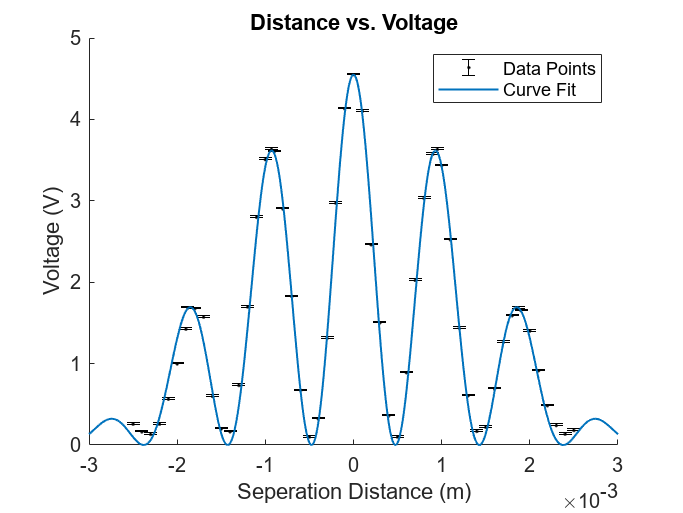

hold on;

legend('Data Points', 'Curve Fit', 'Location', 'NorthEast', 'Interpreter', 'none' );

print('Distance_vs_Voltage.png', '-dpng','-r600');

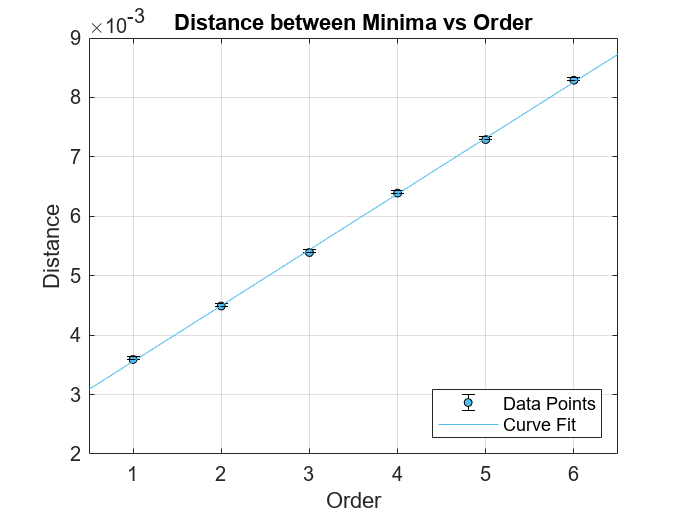

order = [1,2,3,4,5,6];
distance_between_minima = [0.00359,0.00449,0.00539,0.00639,0.00729,0.00829];
dy_2=(0.00005).*ones(1,6);
dx_2=(0.0000000001).*ones(1,6);

figure;
errorbar(order,distance_between_minima,dx_2,dy_2,'o','MarkerFaceColor',"#4DBEEE", 'LineWidth', 0.5, 'MarkerSize', 4, 'Color', 'k')
xlabel('Order')
ylabel('Distance')
grid on
hold on
fplot(@(x) 0.00094*x + 0.002617, 'color',"#4DBEEE")
xlim([0.5 6.5])
ylim([2e-3 9e-3])
legend('Data Points','Curve Fit','Location','SouthEast')
title('Distance between Minima vs Order')

print('Distance_vs_Order.png','-dpng','-r600');

dis_mm = transpose(linspace(0.18,7.2,40))

dis_mm =     0.1800
    0.3600
    0.5400
    0.7200
    0.9000
    1.0800
    1.2600
    1.4400
    1.6200
    1.8000


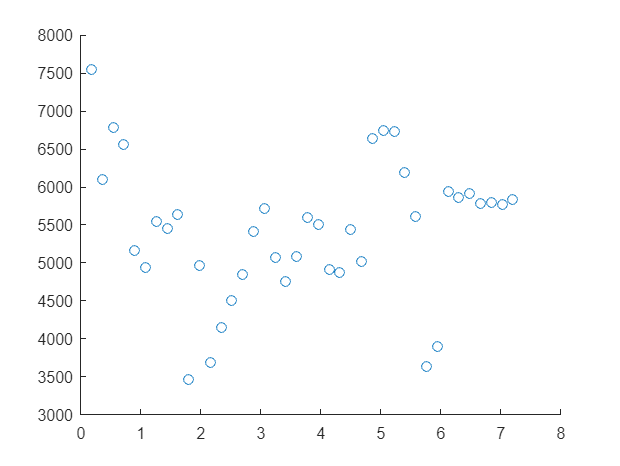

count = [7554,6103,6786,6563,5161,4940,5546,5458,5632,3467,4961,3684,4154,4507,4851,5416,5711,5074,4753,5089,5603,5504,4909,4868,5444,5020,6639,6746,6727,6193,5614,3632,3905,5936,5857,5913,5784,5801,5776,5830];
scatter(dis_mm,count)

dis_mm_measured = [1.93, 2.65, 3.45, 4.23, 5.2]

dis_mm_measured =     1.9300    2.6500    3.4500    4.2300    5.2000


count_trial_2 = [1353, 2780, 3549, 2905, 3000]

count_trial_2 =         1353        2780        3549        2905        3000


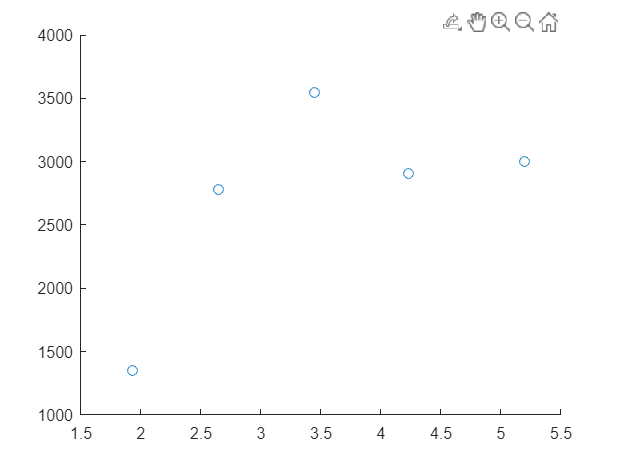

scatter(dis_mm_measured,count_trial_2)

new_dis_mm = linspace(1,6,51)

new_dis_mm =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


counts_new = [265, 335, 364, 330, 260, 290, 510, 810, 1201, 1397, 1160, 695, 407, 458, 1107, 2142, 2711, 2795, 2114, 1113, 452, 644, 1640, 2901, 3625, 3245, 2211, 1070, 466, 675, 1616, 2424, 2907, 2431, 1548, 694, 331, 555, 888, 1291, 1375, 1024, 627, 311, 243, 266, 295, 323, 270, 188, 143]

counts_new =          265         335         364         330         260         290         510         810        1201        1397        1160         695         407         458        1107        2142        2711        2795        2114        1113         452         644        1640        2901        3625        3245        2211        1070         466         675        1616        2424        2907        2431        1548         694         331         555         888        1291        1375        1024         627         311         243         266         295         323         270         188


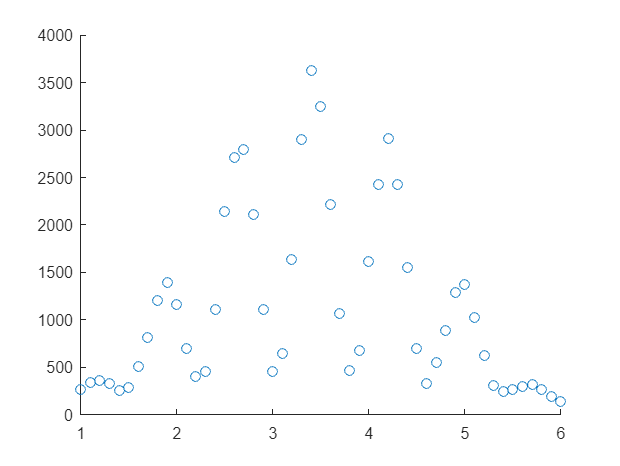

ans = 3625

scatter(new_dis_mm,counts_new)

dim_final_meter = (new_dis_mm - 3.3999999999999).*(10e-4)

dim_final_meter =    -0.0024   -0.0023   -0.0022   -0.0021   -0.0020   -0.0019   -0.0018   -0.0017   -0.0016   -0.0015   -0.0014   -0.0013   -0.0012   -0.0011   -0.0010   -0.0009   -0.0008   -0.0007   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0001    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025


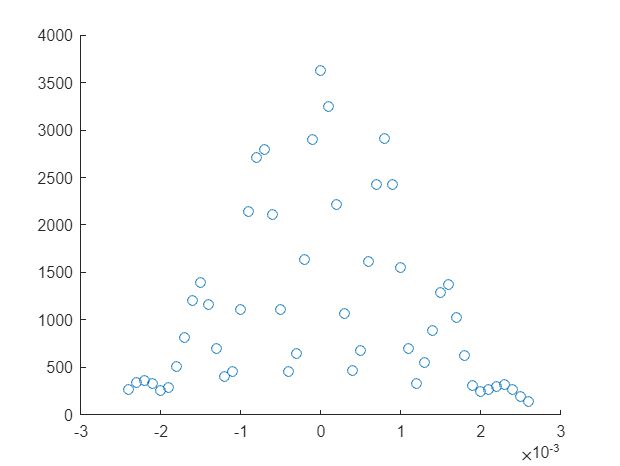

counts_final = counts_new;
scatter(dim_final_meter,counts_final)

figure;
dy_3 = 15.*ones(1,51)

dy_3 =     15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15


dx_3 = 0.0001.*ones(1,51)

dx_3 = 1.0e-04 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


errorbar(dim_final_meter,counts_final,dx_3,dy_3,'.', ...
    'MarkerFaceColor', 		"#4DBEEE", 'LineWidth', 0.5, 'MarkerSize', 4, 'Color', 'k')
hold on
fplot(@(y) 3625*(sin(2*pi*y*(8.885e-05)/(546e-9*1.02))/(2*pi*y*(8.885e-05)/(546e-9*1.02)))^2*(cos(2*pi*y*(0.0003514)/(546e-9*1.02)))^2,[-0.003 0.003],'color',"#0072BD",'LineWidth',1)

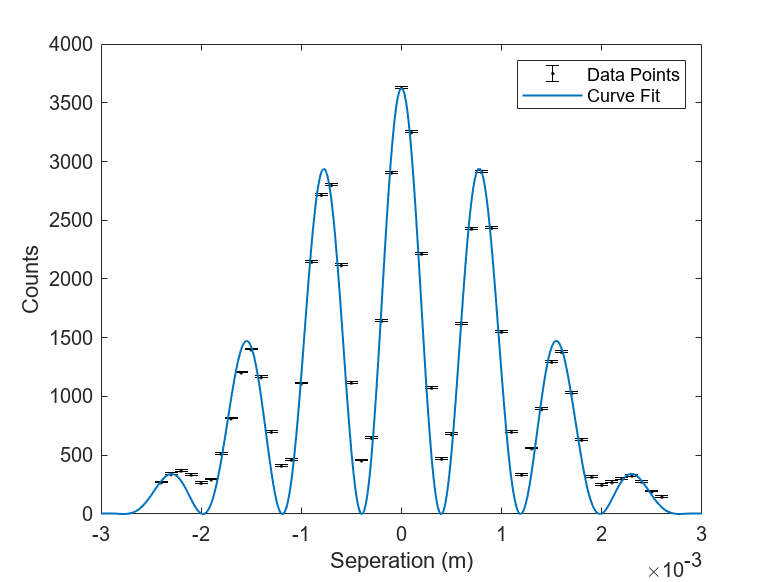

%fplot(@(y) 3625*(sin(2*pi*y*(8.41e-05)/(546e-9*1.02))/(2*pi*y*(8.41e-05)/(546e-9*1.02)))^2*(cos(2*pi*y*(0.0003467)/(546e-9*1.02)))^2,[-0.003 0.003],'color',"#0072BD",'LineStyle','--')
%fplot(@(y) 3625*(sin(2*pi*y*(9.36e-05)/(546e-9*1.02))/(2*pi*y*(9.36e-05)/(546e-9*1.02)))^2*(cos(2*pi*y*(0.0003561)/(546e-9*1.02)))^2,[-0.003 0.003],'color',"#0072BD",'LineStyle','--')

xlabel("Seperation (m)")
ylabel("Counts")
legend('Data Points', 'Curve Fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
print("Lab_7.png","-dpng","-r600")